# Apply component contribution method and analyse solution

## **Author: Ronan Fleming, Leiden University**

## **Reviewers: **

## INTRODUCTION

## PROCEDURE

## Configure the environment

All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'old'];
method = 'remove';
editCobraToolboxPath(basePath,folderPattern,method)

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/directionalityReport/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/old


aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'new'];
method = 'add';
editCobraToolboxPath(basePath,folderPattern,method)

adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/new


initVonBertalanffy

ChemAxon Marvin Beans is installed and working.
	linux-vdso.so.1 (0x00007ffdffdf8000)
	libc.so.6 => /lib/x86_64-linux-gnu/libc.so.6 (0x00007f0c2b55d000)
	libopenbabel.so.5 => /usr/lib/libopenbabel.so.5 (0x00007f0c2b30d000)
	libstdc++.so.6 => /usr/lib/x86_64-linux-gnu/libstdc++.so.6 (0x00007f0c2b0f3000)
	libgcc_s.so.1 => /usr/local/bin/MATLAB/R2021a/sys/os/glnxa64/libgcc_s.so.1 (0x00007f0c2aedb000)
	/lib64/ld-linux-x86-64.so.2 (0x00007f0c2b77d000)
	libdl.so.2 => /lib/x86_64-linux-gnu/libdl.so.2 (0x00007f0c2aed3000)
	libz.so.1 => /lib/x86_64-linux-gnu/libz.so.1 (0x00007f0c2aeb7000)
	libm.so.6 => /lib/x86_64-linux-gnu/libm.so.6 (0x00007f0c2ad68000)
	libgomp.so.1 => /usr/lib/x86_64-linux-gnu/libgomp.so.1 (0x00007f0c2ad23000)
	libpthread.so.0 => /lib/x86_64-linux-gnu/libpthread.so.0 (0x00007f0c2ad00000)

babel must depend on the system libstdc++.so.6 not the one from MATLAB
Trying to edit the 'LD_LIBRARY_PATH' to make sure that it has the correct system path before the Matlab path!
The solu

Load data input for component contribution method

load('data_prior_to_componentContribution')

Run component contribution method

 param.debug = 1;
 [model,solution] = componentContribution(model,combinedModel,param);

Running Component Contribution method


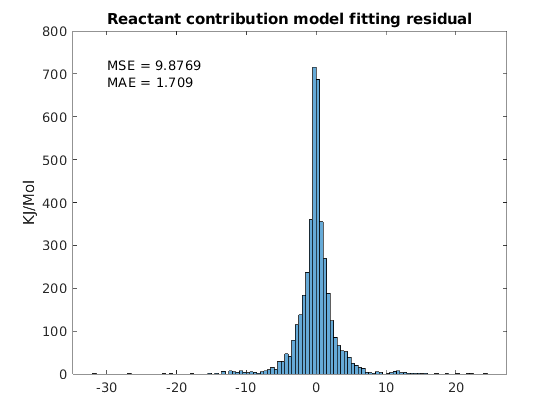

 figure;
 histogram(solution.e_rc)
  text(-30,700,{['MSE = ' num2str(solution.MSE_rc)],['MAE = ' num2str(solution.MAE_rc)]});
 title('Reactant contribution model fitting residual')
 ylabel('KJ/Mol')

 [rcErrorSorted,rcSI]=sort(solution.e_rc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(rcSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_rc(rcSI(i)),combinedModel.rxns{rcSI(i)},rxnFormula{1});
 end

-31.6414	TECRDB_1919	C00002 + C01281  <=> C00013 + C01299 
-26.9545	TECRDB_1929	C00002 + C01281  <=> C00013 + C01299 
-21.9955	TECRDB_1920	C00002 + C01281  <=> C00013 + C01299 
-20.5893	FORM_C00093	 <=> C00093 
-17.7694	FORM_C01127	 <=> C01127 
-15.2367	TECRDB_539	C00002 + C00300  <=> C00008 + C02305 
-15.1381	TECRDB_2655	C00003 + C00197  <=> C00004 + C03232 
-14.375	TECRDB_3728	C00003 + C00469  <=> C00004 + C00084 
-14.2817	TECRDB_374	C00006 + C00342  <=> C00005 + C00343 
-13.4218	TECRDB_237	C00002 + C00062  <=> C00008 + C05945 


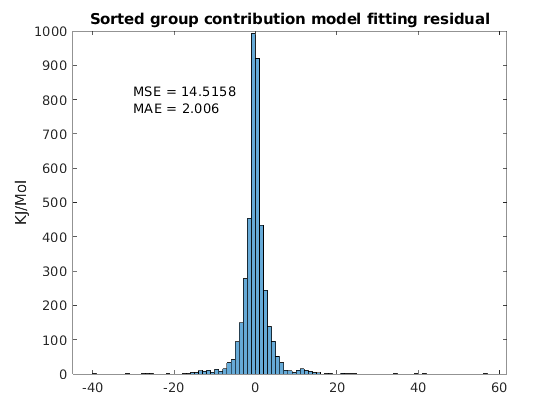

 [gcErrorSorted,gcSI]=sort(solution.e_gc);
 figure;
 histogram(solution.e_gc)
 title('Sorted group contribution model fitting residual')
 ylabel('KJ/Mol');
 text(-30,800,{['MSE = ' num2str(solution.MSE_gc)],['MAE = ' num2str(solution.MAE_gc)]});

[gcErrorSorted,gcSI]=sort(solution.e_gc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(gcSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_gc(rcSI(i)),combinedModel.rxns{gcSI(i)},rxnFormula{1});
 end

-31.6414	FORM_C06670	 <=> C06670 
-26.9545	TECRDB_1919	C00002 + C01281  <=> C00013 + C01299 
-21.9955	FORM_C00469	 <=> C00469 
-25.3984	TECRDB_1929	C00002 + C01281  <=> C00013 + C01299 
-15.9678	FORM_C00093	 <=> C00093 
-15.2367	TECRDB_1920	C00002 + C01281  <=> C00013 + C01299 
-15.6522	FORM_C00084	 <=> C00084 
-13.3079	FORM_C80002	 <=> C80002 
-15.3716	FORM_C01127	 <=> C01127 
-12.4739	TECRDB_2655	C00003 + C00197  <=> C00004 + C03232 


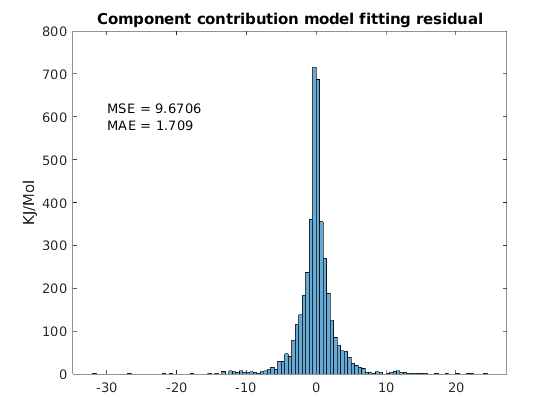

 figure;
 histogram(solution.e_cc)
  text(-30,600,{['MSE = ' num2str(solution.MSE_cc)],['MAE = ' num2str(solution.MAE_cc)]});
 title('Component contribution model fitting residual')
 ylabel('KJ/Mol')

 [rcErrorSorted,ccSI]=sort(solution.e_cc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(ccSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_cc(rcSI(i)),combinedModel.rxns{ccSI(i)},rxnFormula{1});
 end

-31.6414	TECRDB_1919	C00002 + C01281  <=> C00013 + C01299 
-26.9545	TECRDB_1929	C00002 + C01281  <=> C00013 + C01299 
-21.9955	TECRDB_1920	C00002 + C01281  <=> C00013 + C01299 
-20.5893	FORM_C00093	 <=> C00093 
-17.7694	FORM_C01127	 <=> C01127 
-15.2367	TECRDB_539	C00002 + C00300  <=> C00008 + C02305 
-15.1381	TECRDB_2655	C00003 + C00197  <=> C00004 + C03232 
-14.375	TECRDB_3728	C00003 + C00469  <=> C00004 + C00084 
-14.2817	TECRDB_374	C00006 + C00342  <=> C00005 + C00343 
-13.4218	TECRDB_237	C00002 + C00062  <=> C00008 + C05945 


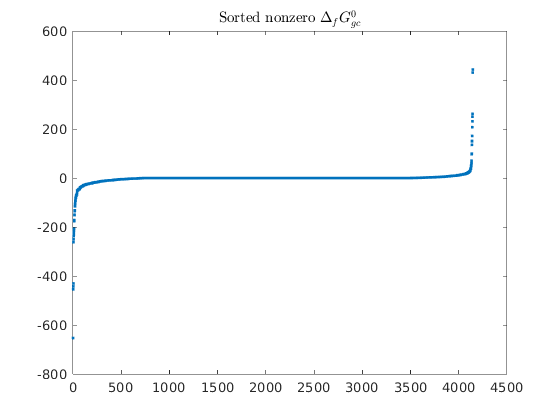

DfG0_gc = solution.DfG0_gc(solution.DfG0_gc~=0);
 DfG0_gc_sorted = sort(DfG0_gc);
 figure;
 plot(DfG0_gc_sorted,'.')
 title('Sorted nonzero $\Delta_{f} G^{0}_{gc}$','Interpreter','latex')